# **NeuMa Raw Dataset Processing**

Here, we aim to demonstrate the data loading and parsing of both the recordings (.xdf files) and the questionnaires (.xls files).

## Importing Data from Questionnaires

The *parseExcelProfiles.m *function parses the .xls file that contains the questionnaire responses for each subject. Each .xls file includes the following information:

- **Demographics****:** A series of demographic indicators namely, age, gender, education, marital status, children (boolean variable) and dominant hand.

- **Personality traits****: **A series of clustered profiling related responses that upon analysis can provide information with respect to the following: (i) Big five personality traits, (ii) Utilitarian/Hedonic shopping motivation, (iii) Visual/Verbal information processing, (iv) Impulse buying behaviour, (v) Variety seeking behaviour and (vi) Bargain Hunting.

- **Consumer Behaviour:** Information related to the participant’s buying behaviour, including: (i) Buying impact factors (i.e. in what extend the product selection is affected by (a) the product’s price, (b) the product’s brand, (c) the applied discount, (d) various product related promotional actions and (e) family/friend recommendation), (ii) Total number of weekly supermarket visits/Visit duration and (iii) The use or not of shopping list.

- **Product Info:** Information related to the products illustrated to the participants. In detail, for each product a broad description regarding the product is provided (e.g. Milk, Cereals, Biscuits, etc.) that is accessed via the file *Leaflet_Product_Descriptions.mat*. Additionally, for each selected product the responses regarding the following questions are provided:

-     - Why was the product selected? - The possible responses regarding this question were: **A - Price:** The product was selected due to its price*,* **B - Brand:** The product was selected due to its brand, **C - Discount:** The product was selected because it was on a discount, **D - Type:** The selection was based on the product's type (e.g. The participant was in need of milk and therefore selected one of the available milks), **E - Need:** The consumer was running out of the selected product and therefore was in need of it, **F - Like:** This was a product that the participant likes, **G - Regular:** This was a product that is regularly bought by the participant, **H - Combination:** This product was selected with the purpose of being combined with another selected product (e.g. cereals were selected, due to the previous selection of milk), **I - Alternative:** The product was selected as it was the closest alternative choice available (e.g. milk of brand A was selected, as milk of brand B was not available), **J - Other:** The product was selected for a reason that is not included in the previous options

- - Is this a familiar product? - The response to this question indicates if the product is frequently bought by the participant (**A - Yes**) or not (**B - No**).

- - Does this product constitute a frequent selection? - The response to this question indicates how familiar the participant is with the specific product. The responses range in a five-point scale (i.e. (**A - totally unfamiliar**) - (**E - completely familiar**)).

clear

 % Add all dependencies (Functions) to the Matlab Path
addpath(genpath('Dependencies\'));
% Add Example Data (Subject 01, chanlocs, Prodct Descriptions) to the Matlab Path
addpath(genpath('RawData_Sample\')); 
subject_ID = 'S01';
S01 = parseExcelProfiles(subject_ID);

subject_struct = struct with fields:
           Page1: [1×1 struct]
           Page2: [1×1 struct]
           Page3: [1×1 struct]
           Page4: [1×1 struct]
           Page5: [1×1 struct]
           Page6: [1×1 struct]
         Profile: [1×1 struct]
    Demographics: [1×1 struct]


load('Leaflet_Product_Descriptions.mat')
for ss=1:6
    for bb=1:24
        pageNo = int2str(ss);
        productNo = int2str(bb);
        S01.(strcat('Page',pageNo)).(strcat('Product',productNo)).ProductInfo.Description ...
        = Product_Descriptions{ss,bb};
   end
end 

## Importing Data from datastreams

### Load sensor coordinates

Load the EEG electrode location coordinates and other electrode related information via the *chanlocs_dsi24.mat*file. 

load('chanlocs_dsi24.mat')
Sensors_exluded = [16,17,20,21,24];

### Load .xdf recording

Load the raw experimental data for each subject using the Matlab xdf modules.

xdf_filename = 'RawData_Sample\S01.xdf'

xdf_filename = 'RawData_Sample\S01.xdf'

myData = load_xdf(xdf_filename);

### Identify the five recorded datastreams

The following procees identifies the exact type of each of the recodrded data streams, with the required information being stored in the field *info* for each data stream.

EEG_stream = []; ET_stream = []; MRK_stream = [];
for i_stream = 1:size(myData,2) %Stream Idenditifaction (Correct Type and NOT empty)
    if (~isempty(myData{1, i_stream}.time_series))
        if strcmp(myData{1,i_stream}.info.type,'EEG')
            EEG_stream = myData{1,i_stream};
        elseif strcmp(myData{1,i_stream}.info.type,'Eyetracker')
            ET_stream = myData{1,i_stream};
        elseif strcmp(myData{1,i_stream}.info.name,'MyMarkerStream3')
            MRK_stream = myData{1,i_stream};
            %MOUSE_stream = myData{1,i_stream};
        elseif strcmp(myData{1,i_stream}.info.name,'MouseButtons')
            MOUSE_stream = myData{1,i_stream};
        elseif strcmp(myData{1,i_stream}.info.name,'MousePosition')
            MOUSE_position = myData{1,i_stream};
        end
    end
end

### EEG preprocessing using in sequence ASR and FORCe

Here, the function *EEG_preprocessing.m*, incorporates the preprocessing steps, including but not limited to bandpass filtering and artefact rejection, applied on the continuous EEG recording. More specifically, raw EEG signals were subjected to a bandpass filter (butterworth, 3rd order, zero-phased) within 0.5–45 Hz, followed by the removal of artifactual activity via the combined use of Artifact Subspace Reconstruction (ASR) and FORCe.

Fs = str2num(EEG_stream.info.nominal_srate);
EEG_raw = EEG_stream.time_series;
EEG_raw=EEG_raw(setdiff([1:24],Sensors_exluded),:);
[EEG_filt, EEG_clean] = EEG_preprocessing(EEG_raw, Fs, chans);

Finding a clean section of the data...
Determining time window rejection thresholds...done.
Keeping 28.9% (106 seconds) of the data.
Apparently you do not have EEGLAB's pop_select() on the path.


An error occurred while trying to identify a subset of clean calibration data from the recording.
If this is because do not have EEGLAB loaded or no Statistics toolbox, you can generally
skip this step by passing in 'off' as the ReferenceMaxBadChannels parameter.
Error details: 
  Reference to non-existent field 'xmin'.
  occurred in: 
    clean_windows: 149
    clean_asr: 146
    EEG_preprocessing: 14
    

**Illustration of the raw and preprocessed EEG data**

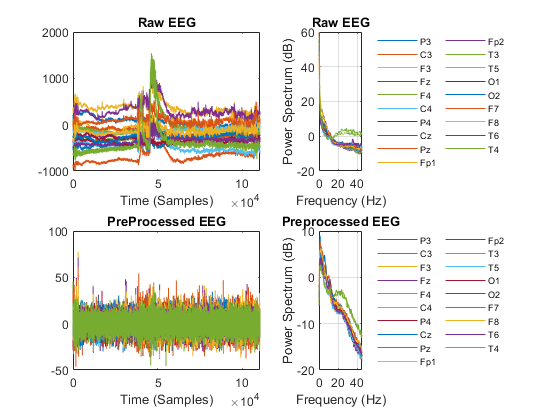

figure(1),clf,subplot(2,2,1),plot(EEG_raw'),title('Raw EEG'),xlabel('Time (Samples)');
subplot(2,2,3),plot(EEG_clean);title('PreProcessed EEG'),xlabel('Time (Samples)')
subplot(2,2,2),pspectrum(EEG_raw',Fs,'FrequencyLimits',[0 45],'FrequencyResolution',0.5)
legend(chans.labels,'Location','eastoutside','fontsize',7,'numcolumns',2)
legend('boxoff'),title('Raw EEG')
subplot(2,2,4),pspectrum(EEG_clean,Fs,'FrequencyLimits',[0 45],'FrequencyResolution',0.5)

legend(chans.labels,'Location','eastoutside','fontsize',7,'numcolumns',2)
legend('boxoff'),title('Preprocessed EEG')

**Incorporating the cleaned EEG data in the subject's structure**

S01.EEG_clean = EEG_clean;

### ET preprocessing using linear interpolation

In the following, linear interpolation is applied to the gaze data in order to fill in missing data points (taking place during spontaneous eye blinking) using the  function *interpNANs.m*.

ET_raw = ET_stream.time_series;
[nans,ET_clean] = interpNANs(ET_raw,[],'linear');

nSensors = 6

nSamples = 43200

**Illustration of the raw and preprocessed ET data**

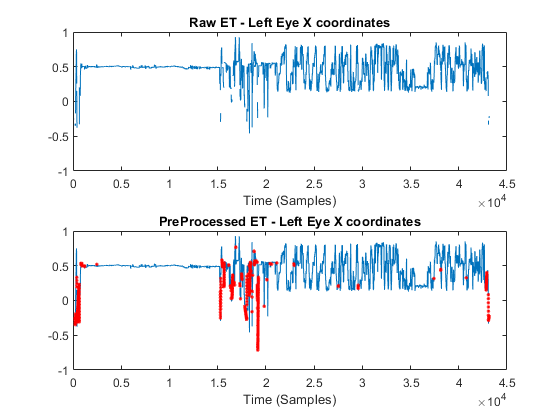

mynans = find(nans(1,:)==1);
figure(2),clf
subplot(2,1,1),plot(ET_raw(1,:)')
title('Raw ET - Left Eye X coordinates'),xlabel('Time (Samples)');
subplot(2,1,2),plot(ET_raw(1,:)'),hold on, plot(mynans,ET_clean(1,mynans)','.r')
title('PreProcessed ET - Left Eye X coordinates'),xlabel('Time (Samples)');  

** Incorporating the cleaned ET data in the subject's structure**

S01.ET_clean = ET_clean;

### Product-Based Segmentation and Labeling   

Here, the product-related data and information are incorporated in the subject's struct. 

[ET,labels] = segmentationLeaflet(MRK_stream, MOUSE_stream, MOUSE_position, ET_stream);
EEG = converterET2EEG (ET, ET_stream, EEG_stream);
load('Leaflet_Product_Descriptions.mat')
for ss=1:6
    for bb=1:24
        pageNo = int2str(ss);
        productNo = int2str(bb);
        S01.(strcat('Page',pageNo)).(strcat('Product',productNo)).EEG_segments = ...
        EEG.(strcat('Page',pageNo)).(strcat('Product',productNo));
        S01.(strcat('Page',pageNo)).(strcat('Product',productNo)).ET_segments = ...
            ET.(strcat('Page',pageNo)).(strcat('Product',productNo));
        S01.(strcat('Page',pageNo)).(strcat('Product',productNo)).ProductInfo.Bought = ...
            labels(ss,bb);
   end
end   

### The final format of the subject's struct

Each struct contains the following data and information for each subject:

struct_cont = fieldnames(S01);
fprintf('%s\n',struct_cont{:});

Page1
Page2
Page3
Page4
Page5
Page6
Profile
Demographics
EEG_clean
ET_clean


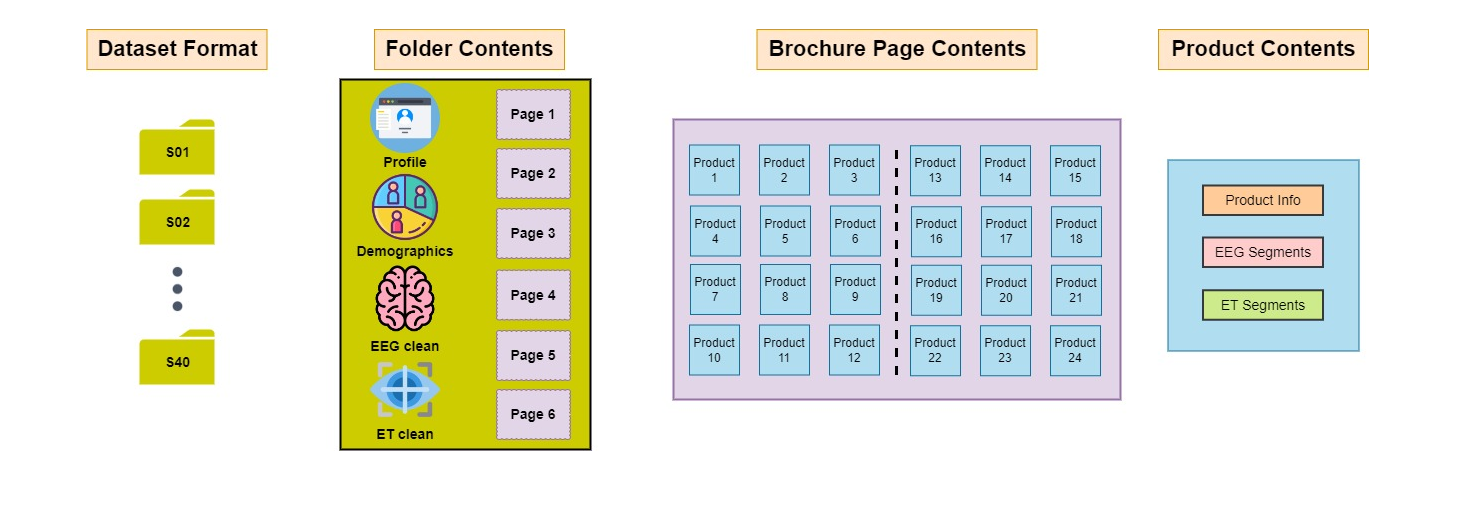

figure(3),clf,imshow('PreProcessed_Format.jpg');